# Homework 03 - Models & Uncertainty

Please add your name, section, and semester information to the fields below

StudentName = "Edward Ramirez"; % First Last
Section = "A09"; % ex. A01
Semester = "Spring 2025"; % ex. Fall 2023

## Background

For this Block, you will be investigating a test rig designed for material failure testing to determine if it is suitable for a range of different materials, as well as what improvements are necessary to the design. The test rigs (Figure 1) are designed to place a test specimen under uniaxial loading and can measure the specimen’s deformation and the associated applied load. You client has seen discrepancies between the measured and known material properties of test samples. You must determine the source and extent of these discrepancies and make recommendations for usage and improvements to the rig supported by your data. 

You will be testing several aspects of the rig to determine the source of the discrepancies from expected results due to the rig design and recommending possible corrections. First you will the calibrate the sensors to get an understanding of the range and uncertainty of the measurements they provide. 

The first week of the Block will focus on understanding the calibration process for the force transducer and signal path (i.e. the combined Wheatstone bridge, amplifier, and filter) and determining if it meets the design values you will calculate in this homework. After going through the calibration procedure, you will also determine if the rig is capable of testing and charactering the performance of a climbing sling.

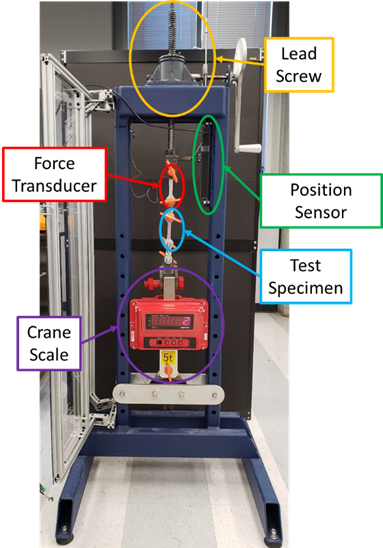

*Figure 1: Test rig design showing orientation of force transducer and test specimen during stress/strain testing. Test specimen is strained by use of a lead screw whose position is measured by a position sensor. The resulting applied force is measured by a force transducer consisting of an aluminum 6061-T6 dog bone and strain gauge calibrated by use of a crane scale as a standard.*

## Data

A sample dataset, *Homework_3_Data.mat*, that you will use in this homework analysis can found in the assignment on Canvas.

load( 'Homework_3_Data.mat' );

## Force Sensor Calibration - Analytical Model

Forces are hard to measure directly in many objects, so force transducers are used to measure force indirectly. One method to do this is to measure the deformation of an object with a known relationship to the applied force (e.g. a spring scale). You will now explore the design of a force transducer and how it produces a signal that can be read and processed by the ELVIS III to develop an analytical calibration equation. To do this you are going to model the signal path of the force transducer and its conditioning circuit. Since the Wheatstone bridge in this path is slightly non-linear, you will do this by creating a set of reasonable force values, calculating the resulting voltages, and then fitting the data to create a calibration model.

### Force Transducer Dog Bone

The force transducer used in the lab test rig consists of an Al-6061-T6 aluminum dog bone (Figure 2) with an attached strain gauge. The dog bone used in the force transducer is designed such that in the constant cross-section region, where the strain gauge is attached, it can be assumed that the force applied acts as uniaxial normal stress. By knowing the material properties and the dimensions of the dog bone a model can be created of the resulting strain from an applied load. It is also important to know the physical limits of the dog bone that the assumed relationships the calibration model is based upon.

  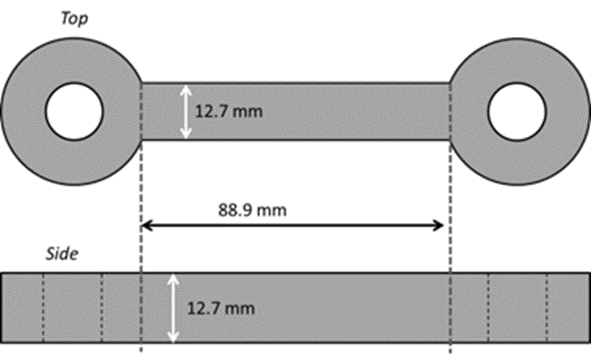

*Figure **2: Force transducer dog bone schematic*

% Material and Dimensional Properties of the Force Transducer Dog Bone
E_GPa = 68.9; % GPa, Young's modulus of 6061-T6 alumuinum
sigma_yield_MPa =276; % MPa, yield strengh of 6061-T6 alumuinum
width_mm = 12.7; % mm, width of force transducer dog bone
thickness_mm = 12.7; % mm, thickness of force transducer dog bone
length_mm = 88.9; % mm, length of constant cross-section

#### Problem 1

What is the cross-sectional area,$A$, of the dog bone in **meters squared**?

% Code here to solve for A_m2
A_m2 = (width_mm.*thickness_mm).*1e-6; % m^2, cross sectional area of dog bone

fprintf( 'A = %.3g m^2\n', A_m2 ); % Print answer

A = 0.000161 m^2


#### Problem 2

What is the theoretical maximum load, $F_{\max }$, in **kilonewtons** that can be applied to the force transducer before the dog bone experiences yielding which will damage the transducer?  (*Hint: should be between 40 and 50 kN. Keep this value in mind in lab so you do not break the transducer!*)

% Code here to solve for F_max_kN
F_max_kN = A_m2.*sigma_yield_MPa.*1e3; % kN, cross sectional area of dog bone

fprintf( 'F_max = %.3g kN\n', F_max_kN); % Print answer

F_max = 44.5 kN


You will now create a dataset of force values that you will use to determine the final voltage acquired by the ELVIS III board based upon the assumed relationships of the components in the force transducer signal path. The resulting values associated with the maximum load in Problem 2 will be used to check your answers.

#### Problem 3

Create a vector of at least 10 applied forces, $F_{\textrm{applied}}$, from 0 to the maximum allowable force from Problem 2. Calculate a vector of normal stresses, $\sigma$, in **Pascal** in the dog bone for the vector of applied loads. What is the maximum stress allowable, $\sigma_{\max }$, in **Pascal**? (*Hint: It should be the same as the yield stress!*)

% Code here to solve for sigma_Pa and sigma_max_Pa
appliedForces = linspace(0, F_max_kN, 10); % range of applied forces from 0 to F_max in Kilonewtons
sigma_Pa = (appliedForces./A_m2).*1e3; % range of resultant normal stresses in Pascal (N/m^2)
sigma_max_Pa = max(sigma_Pa); % Pa, maximum normal stress

fprintf( 'sigma_max = %.4f Pa\n', sigma_max_Pa ); % Print answer

sigma_max = 276000000.0000 Pa


It is assumed that as long as the load applied to force transducer is below the yielding point of the material, the resulting deformation will act according to Hooke’s law of linear elasticity. 

#### Problem 4

Calculate a vector of strains in the dog bone, $\epsilon$, for the vector of applied loads, $F_{\textrm{applied}}$. What is the maximum resulting strain, $\epsilon_{\max }$,  in the gauge area? (*Hint: It should be between 0.002 and 0.005.*)

% Code here to solve for epsilon and epsilon_max
deltaLength = (appliedForces.*length_mm)./(A_m2.*E_GPa.*1e6); % mm, change in length
epsilon = (deltaLength)./(length_mm); % m/m, strain
epsilon_max = max(epsilon); % m/m, maximum strain

fprintf( 'epsilon_max = %.3g\n', epsilon_max ); % Print answer

epsilon_max = 0.00401


### Strain Gauge 

Measuring the strain directly is possible in some applications by measuring the deformation of a gauge area and dividing by the original length. However, for the force transducer dog bone this is difficult due to the small change in length that would result. Instead, a strain gauge will be attached to the dog bone in the gauge area. The resistance of the strain gauge varies under load, which is how it is used to measure the small strains that the force transducer experiences. *(Note: The specification sheet for the strain gauge initial unstrained resistance,* $R_{G,0}$*, and the gauge factor, *$\textrm{GF}$*, and can be found in the lab resources.)* 

% Strain Gauge Properties
R_G_0_ohms = 120; % Ohms, unstrained initial resistance
GF = 2.07; % Gauge factor

#### Problem 5

Calculate a vector of instantaneous resistances of the strain gauge, $R_G$, in **Ohms** as a function of the strain, $\epsilon$. What is the maximum resulting resistance, $R_{G,\max }$, of the strain gauge? (*Hint: It should be between 120.9 and 121.1 Ohms.*)

% Code here to solve for R_ohms and R_max_ohms
R_G_ohms = R_G_0_ohms.*(1 + GF.*epsilon); % ohms, strain gauge resistance
R_G_max_ohms = max(R_G_ohms); % ohms, maximum strain gauge resistance

fprintf( 'R_G_max = %.4f\n', R_G_max_ohms ); % Print answer

R_G_max = 120.9950


### Wheatstone Bridge

Wheatstone bridges allow a small change in resistance to be measured relative to an initial voltage value, which provides better sensitivity than measuring changes in resistance directly. Figure 3 shows a schematic of a Wheatstone bridge and the actual circuity you will be using for the lab. 

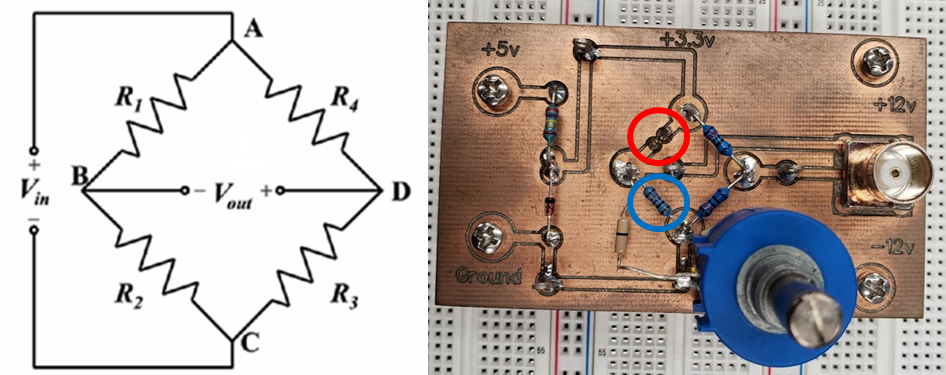

*Figure **3**: Wheatstone bridge schematic (left) and Wheatstone circuit board (right) used in force transducer signal path. The **red** circle highlights the connection terminals for the strain gauge (*$R_4$*) and the **blue** circle the resistor (*$R_3$*) modified by the potentiometer. The resistors (*$R_1$, $R_2$, & $R_3$*) were chosen to be the same 120 Ω as the initial strain gauge resistance. Note that the BNC cable polarity uses the voltage at D as positive and B as negative.*

% Wheatstone Bridge Properties
V_in_V = 3.3; % V, Wheatstone bride input voltage
R_W_ohms = 120; % Ohms, Wheatstone bridge resistance values

#### Problem 6

Calculate the vector of Wheatstone output voltages,$V_{\textrm{out}}$, as a function of the strain gauge resistances, $R_G$, if the Wheatstone input voltage,$V_{\textrm{in}}$, is 3.3 V and the potentiometer resistance ($R_3$) and the set of Wheatstone bridge resistors ($R_1$ & $R_2$) are the same as the strain gauge initial unstrained resistance, $R_{G,0}$ (i.e. the bridge is initially balanced). What is the maximum resulting output voltage from the Wheatstone bridge, $V_{\textrm{out},\max }$, in **Volts**? (*Hint: It should be between 0.006 and 0.007 V.*)

% Code here to solve for V_out_V and V_out_max_V
V_out_V = V_in_V.*((R_G_ohms-R_W_ohms)./(2.*(R_G_ohms+R_W_ohms))); % V, Wheastone bridge voltage
V_out_max_V = max(V_out_V); % V, maximum Wheastone bridge voltage

fprintf( 'V_out_max = %.3g V\n', V_out_max_V ); % Print answer

V_out_max = 0.00681 V


### Amplifer & Filter

The voltage change from the Wheatstone bridge is on the order of millivolts for the test rig setup. Since this is a similar order of magnitude as the Elvis III’s resolution, an amplifier and low-pass filter is used to boost the voltage and clean the signal.

G_amp = 200; % V/V, amplifer gain

#### Problem 7

Calculate the vector of voltages,$V_{\textrm{ELVIS}}$, that will be acquired by the ELVIS III board after the amplifier and low-pass filter. (The signal produced by the force transducer can be assumed to have a 0 Hz frequency.) What is the maximum voltage acquired by the ELVIS board, $V_{\textrm{ELVIS},\max }$, in **Volts**? (*Hint: It should be between 1.35 and 1.37 V.*)

% Code here to solve for V_ELVIS_V and V_ELVIS_max_V
V_ELVIS_V = V_out_V.*G_amp % V, voltage acquired by the ELVIS III board

V_ELVIS_V =          0    0.1520    0.3038    0.4554    0.6070    0.7584    0.9096    1.0607    1.2117    1.3625


V_ELVIS_max_V = max(V_ELVIS_V); % V, maximum voltage acquired by the ELVIS III board

fprintf( 'V_ELVIS_max = %.4f V\n', V_ELVIS_max_V ); % Print answer

V_ELVIS_max = 1.3625 V


### Design Calibration Model

In order to use the force transducer, a calibration model must be created that can be used to relate the acquired voltage to the applied load. All of the components have a linear relationship between their inputs and outputs. The Wheatstone bridge is non-linear. However, for small changes in resistance that are much smaller than the initial resistance, the relationship between the resistance change and voltage output can be modeled as linear with little error. Therefore, the design calibration equation will be modeled as a linear relationship between the acquired voltage and the applied load.

#### Problem 8

Using the* fit()* function and create a linear model with the acquired ELVIS voltage, $V_{\textrm{ELVIS}}$, as the independent variable and the applied force, $F_{\textrm{applied}}$, as the dependent variable. What is the designed gain, $G_{\textrm{design}}$, and force offset,$F_{0,\textrm{design}}$, of the force transducer and the signal path in **Newtons per Volt **and **Newtons** respectively? *(Hint: The gain should be between 31,000 and 33,000 N/V and the force offset between -50 and 50 N.)* 

% Code here to solve for G_design_N_V and F_0_design_N
[curve8, goodness8] = fit(V_ELVIS_V', (appliedForces.*1e3)', 'poly1');
G_design_N_V = curve8.p1;
F_0_design_N = curve8.p2;

fprintf( 'G_design = %.4f N/V, F_0_design = %.3g N\n', G_design_N_V, F_0_design_N ); % Print answer

G_design = 32671.5070 N/V, F_0_design = -27.3 N


## Force Sensor Calibration - Statistical Model

The derivation of the design calibration equation made many assumptions about the behavior of the individual components. Additionally, there may be effects from the rig, components, and outside factors that could influence the calibration equation. (The strain gauge and Wheatstone bridge are especially sensitive to small changes.) Both of these factors will cause uncertainty of the predicted force values. Once way to address these issues is to create a calibration equation by applying several known forces and measure resulting voltages. A statistical model can then be created which not only captures an expected force versus voltage relationship, but also a measure of the uncertainty of the model. 

In lab you will create a statistical calibration model by attaching a crane scale to your rig and using it as calibration standard. Known forces will then be applied to the rig and a set of resulting voltages will be measure by the ELVIS III board. From this you will create a calibration model for the force versus voltage relationship of the form:


$$F\left(V\right)=G_{\textrm{FT}} \cdot V+F_0$$


A sample set of calibration data using the crane scale can be found in “Homework_3_Data.mat” where “V_FT_V” is the measured ELVIS voltage from the force transducer and “m_scale_kg” is the **mass** displayed by the scale in **kilograms**.

### Expected Force Value

Similar to the design calibration, you are going to model the force transducer calibration as a linear model. However, for this part you are going to account for the error between the known applied forces and the model you create of the expected values based upon the forces. This information will be used to determine the uncertainty of measurements using the calibration model. During lab you apply forces in the range of expected values the rig will be used for to create a calibration model that is valid in those ranges. Be careful to not exceed the specified loads as you can damage the force transducer or the rig! 

#### Problem 9

Using the* fit()* function and create a linear model with the acquired ELVIS voltage,$V_{\textrm{FT}}$, as the independent variable and the applied calibration forces, $F_{\textrm{applied}}$, as the dependent variable (remember that the crane scale displays loads in kilograms). Save both the model fit object and the goodness of fit as both will be used later.

What is the gain, $G_{\textrm{FT}}$, and force offset,$F_0$, of the force transducer and the signal path in **Newtons per Volt **and **Newtons** respectively? *(Hint: The gain should be between 27,000 and 29,000 N/V and the force offset between -3,000 and -2,000 N.)* 

% Code here to solve for G_FT_N_V and F_0_N
[curve9, goodness9] = fit(V_FT_V, m_scale_kg.*9.81, 'poly1')

curve9 =      Linear model Poly1:
     curve9(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =   2.809e+04  (2.74e+04, 2.878e+04)
       p2 =       -2783  (-3132, -2434)

goodness9 = struct with fields:
           sse: 2.0071e+05
       rsquare: 0.9994
           dfe: 6
    adjrsquare: 0.9993
          rmse: 182.8966


G_FT_N_V = curve9.p1; % N/V, calibration gain
F_0_N = curve9.p2; % F, calibration force offset

fprintf( 'G_FT = %.4f N/V, F_0 = %.4f N\n', G_FT_N_V, F_0_N ); % Print answer

G_FT = 28093.4634 N/V, F_0 = -2782.9037 N


#### Problem 10

You will be entering the calibration equation into the LabVIEW VI to collect data. The most common issue you will see during data collection which will cause errors is variations in the offset voltage,$V_0$, value when no force is applied. For this reason, it is sometime helpful to express the force transducer calibration equation in the form:


$$F\left(V\right)=G_{\textrm{FT}} \left(V-V_0 \right)$$


The offset voltage in the equation can easily be updated in this form if shifts in the voltage are detected without having the recalibrate the sensor (generally the gain will not change).

What is the value of the offset voltage of the calibration model in this form in Volts? *(Hint: The offset voltage should be between 0.0 and 0.1 V.)*

% Code here to solve for V_0_V
V_0_V = -(F_0_N)./(G_FT_N_V); % V, calibration voltage offset

fprintf( 'V_0 = %.3g V\n', V_0_V ); % Print answer

V_0 = 0.0991 V


### Force Uncertainty

The error between the known force values and the expected force values from the calibration models can be used to predict the error in future measures. This predicted error is known as uncertainty. Fortunately, MATLAB calculates the sample standard deviation (called the Root Mean Squared Error (RMSE) in goodness of fit object output) the during the creation of the model using the *fit()* function. By assuming a normal distribution around the expected value, the uncertainty of future values and the uncertainty of the model coefficients based upon the data used in the model can be calculated.

#### Problem 11

Using the goodness of fit object from Problem 9, what is the sample standard deviation, $s_{\textrm{FT}}$, of the data used in the calibration model in **Newtons**? *(Hint: The sample standard deviation should be between 170 and 190 N.)*

% Code here to solve for s_N
s_FT_N = goodness9.rmse; % N, sample standard deviation

fprintf( 's_FT = %.3g N\n', s_FT_N ); % Print answer

s_FT = 183 N


#### Problem 12

What is the uncertainty of the force transducer model (K = 2, 95.4% prediction interval), $U_{\textrm{FT}}$, in **N **for a single future measurement*? (Hint: The force transducer prediction interval uncertainty should be between 340 and 380 N.)*

% Code here to solve for U_FT_N
K = 2;
U_FT_N = s_FT_N.*K; % N, prediction interval uncertainty

fprintf( 'U_FT = %.3g N\n', U_FT_N ); % Print answer

U_FT = 366 N


#### Problem 13

Create a well formatted figure showing the data, the model, and the prediction interval for the force transducer calibration.

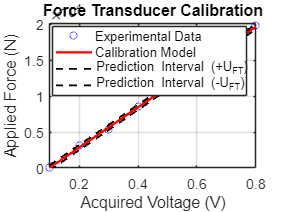

% Code here for figure
figure; hold on; grid on; box on;

scatter(V_FT_V, m_scale_kg.*9.81, 'bo', 'DisplayName', 'Experimental Data');

V_fit = linspace(min(V_FT_V), max(V_FT_V), 100); % Voltage range for model
F_fit = G_FT_N_V * (V_fit - V_0_V); % Apply the calibration model equation
plot(V_fit, F_fit, 'r-', 'LineWidth', 2, 'DisplayName', 'Calibration Model');
U_FT_upper = F_fit + U_FT_N; % Upper bound of prediction interval
U_FT_lower = F_fit - U_FT_N; % Lower bound of prediction interval
plot(V_fit, U_FT_upper, 'k--', 'LineWidth', 1.5, 'DisplayName', 'Prediction Interval (+U_{FT})');
plot(V_fit, U_FT_lower, 'k--', 'LineWidth', 1.5, 'DisplayName', 'Prediction Interval (-U_{FT})');

xlabel('Acquired Voltage (V)');
ylabel('Applied Force (N)');
title('Force Transducer Calibration');
legend('Location', 'best');
set(gca, 'FontSize', 12); % Set font size for axis labels
xlim([min(V_FT_V) max(V_FT_V)]); % Limit x-axis to the voltage range
ylim([min(m_scale_kg .* 9.81) max(m_scale_kg .* 9.81) + U_FT_N]); % Limit y-axis to force range

hold off;

## Displacement Sensor Calibration

When designing testing equipment, it is important to match the transducers and sensors to the application. The range of the sensors should exceed the range of measurements you will conduct during the experiment and ideally the uncertainty in a measurement should be *at least one* order of magnitude lower than the value being measured (i.e. if you are measuring displacements on the order of millimeters, the uncertainty of the sensor should be at least on the order of tenths of millimeters).  However, there are usually tradeoffs between range and uncertainty for sensors that must be balanced for your application.

The position sensor selected in the design of the test rig was the Honeywell SMART position sensor (see lab reference materials for specifications). Similar to the force transducer, you will determine the suitability of the position sensor by calibrating the sensor, calculating the uncertainty, and then comparing the sensor uncertainty to your test results. The file *“Homework_3_Data.mat” *contains a sample set of position sensor calibration data where *“X_PS_mm”* are positions in **millimeters** of the sensor head measured by a ruler and *“V_PS_V”* are the measured voltages by the ELVIS board in **volts**.

#### Problem 14

Using the* fit()* function and create a linear model with the acquired ELVIS voltage,$V_{\textrm{PS}}$, as the independent variable and the measured positions, $X_{\textrm{PS}}$, as the dependent variable. Save both the model fit object and the goodness of fit as both will be used later.

What is the gain,$G_{\textrm{PS}}$, and position offset, $X_0$, of the position sensor and the signal path in **millimeters per volt **and **millimeters** respectively? *(Hint: The gain should be between 50 and 70 mm/V and the offset between -200 and -100 mm.)* 

% Code here to solve for G_PS_mm_V and X_0_mm
[curve14, goodness14] = fit(V_PS_V, X_PS_mm, 'poly1')

curve14 =      Linear model Poly1:
     curve14(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =       59.53  (58.2, 60.85)
       p2 =      -159.1  (-163.2, -155)

goodness14 = struct with fields:
           sse: 2.4041
       rsquare: 0.9991
           dfe: 9
    adjrsquare: 0.9990
          rmse: 0.5168


G_PS_mm_V = curve14.p1; % mm/V, calibration gain
X_0_mm = curve14.p2; % mm, calibration offset

fprintf( 'G_PS = %.3g mm/V, X_0 = %.3g mm\n', G_PS_mm_V, X_0_mm ); % Print answer

G_PS = 59.5 mm/V, X_0 = -159 mm


#### Problem 15

Using the goodness of fit object from Problem 14, what is the sample standard deviation, $s_{\textrm{PS}}$, of the data used in the calibration model in **millimeters**? *(Hint: The sample standard deviation should be between 0.4 and 0.6 mm.)*

% Code here to solve for s_N
s_PS_mm = goodness14.rmse; % mm, sample standard deviation

fprintf( 's_PS = %.3g mm\n', s_PS_mm ); % Print answer

s_PS = 0.517 mm


#### Problem 16

What is the uncertainty of the position sensor model (K = 2, 95.4% prediction interval), $U_{\textrm{PS}}$, in **millimeters **for a single future measurement*? (Hint: The force transducer prediction interval uncertainty should be between 0.8 and 1.2 mm.)*

% Code here to solve for U_PS_m
U_PS_mm = s_PS_mm.*K; % mm, prediction interval uncertainty

fprintf( 'U_PS = %.3g mm\n', U_PS_mm ); % Print answer

U_PS = 1.03 mm


#### Problem 17

Create a well formatted figure showing the data, the model, and the prediction interval for the position sensor calibration.

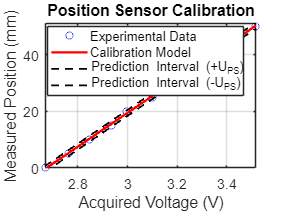

% Code here for figure
figure; hold on; grid on; box on;

scatter(V_PS_V, X_PS_mm, 'bo', 'DisplayName', 'Experimental Data');
V_fit = linspace(min(V_PS_V), max(V_PS_V), 100); % Voltage range for model
X_fit = G_PS_mm_V.*V_fit + X_0_mm; % Apply the calibration model equation
plot(V_fit, X_fit, 'r-', 'LineWidth', 2, 'DisplayName', 'Calibration Model');
U_PS_upper = X_fit + U_PS_mm; % Upper bound of prediction interval
U_PS_lower = X_fit - U_PS_mm; % Lower bound of prediction interval
plot(V_fit, U_PS_upper, 'k--', 'LineWidth', 1.5, 'DisplayName', 'Prediction Interval (+U_{PS})');
plot(V_fit, U_PS_lower, 'k--', 'LineWidth', 1.5, 'DisplayName', 'Prediction Interval (-U_{PS})');

xlabel('Acquired Voltage (V)');
ylabel('Measured Position (mm)');
title('Position Sensor Calibration');
legend('Location', 'best');
set(gca, 'FontSize', 12); % Set font size for axis labels
xlim([min(V_PS_V) max(V_PS_V)]); % Limit x-axis to the voltage range
ylim([min(X_PS_mm) max(X_PS_mm) + U_PS_mm]); % Limit y-axis to position range

hold off;

## Signal Processing

Just as in Block 2, the signal that is recorded during the experiments will have noise and errors that must be corrected to get an accurate and precise representation of the force versus displacement relationships that will be used in the material testing. You will correct this in the data you collect in several ways. Figure 4 shows an example data that shows the signal processing you will conduct to attempt to reduce the error in the measurements.

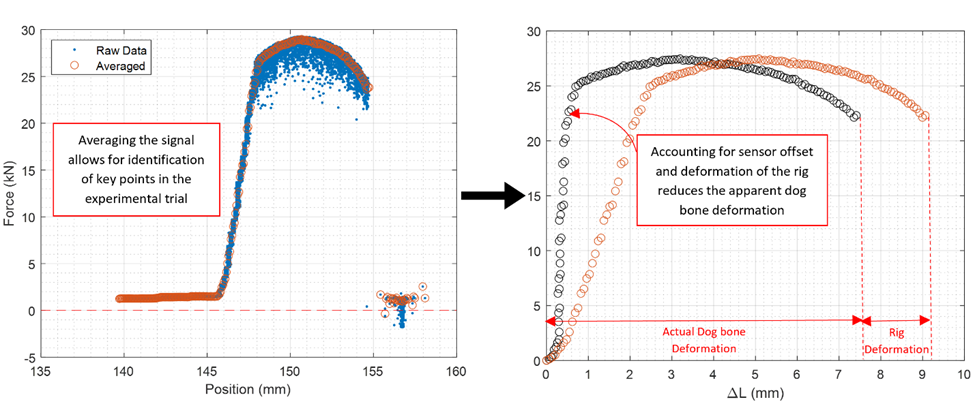

*Figure 4: (left) Example force vs position data from an aluminum 6061-T6 stress-strain test. This data set needs several corrections before analysis. Noise has been reduced by averaging the force values for each discrete position value. There is also extraneous data before and after the loading of the test specimen that is not needed for the analysis. **There is also an error in the offset voltage value in the force transducer calibration equation, which has shifted the force data. (right) Finally, the deformation of the test rig must be accounted for before calculating the stress and strain relationship for the specimen.*

The file *“Homework_3_Data.mat”* contains a sample set of data where *“F_dogbone_N”* is the force on the rig measured by the force transducer in Newtons and *“X_dogbone_mm”* is the measured position in millimeters by the position sensor.

### Random Noise

The force transducer is susceptible to random noise. This will be reduced by averaging the forces corresponding to discrete displacement values from the position sensor. The help with this process you have been supplied with the function *smoothForceDisplacementData(). *

#### Problem 18

Using the function *smoothForceDisplacementData()*, smooth the sample dog bone force and displacement data.

% Code here to solve for denoised F_dogbone_N and X_dogbone_mm
[denoised_X_dogbone_mm, denoised_F_dogbone_N] = smoothForceDisplacementData(X_dogbone_mm, F_dogbone_N);

### Segmentation

Since the position sensor measures the position of the lead screw relative to the frame of the rig, not the deformation of the test specimen directly, the second type of correction needed is the elimination of the extraneous data before (slack in the system) and after the loading of the test specimen (part failure). The are several ways of doing this, but the easiest is to plot the data and pick the position values where this occurs visually. You can then use the values to segment the force and position data.

#### Problem 19

At what position value does the test specimen start being loaded, $X_{\textrm{start}}$? At which value has it failed and is no longer loaded, $X_{\textrm{end}}$? *(Hint: The loading starts approximately between 155.55 and 155.65 mm. The failure occurs approximately between 164.70 and 164.80 mm.)*

% Code here to solve for denoised X_start_mm and X_end_mm
X_start_mm = 155.604;
X_end_mm = 164.737;

#### Problem 20

Using the points identified in Problem 19, segment the force and position data to remove the data before the dog bone was loaded and after the dog bone failed.

% Code here to solve for segement dataset
datasetRange = denoised_X_dogbone_mm >= X_start_mm & denoised_X_dogbone_mm <= X_end_mm;

denoised_X_dogbone_mm = denoised_X_dogbone_mm(datasetRange);
denoised_F_dogbone_N = denoised_F_dogbone_N(datasetRange);

### Bias and Offset Error

If drift in the force transducer offset voltage is not corrected in the calibration equation, the force data may be shifted away from zero. This can be corrected afterwards to re-zero the data. Additionally, the position sensor measures position from an arbitrary reference point. Since you want to measure the displacement of the material under load, the position data too must be corrected. Once you have corrected both the force and position data, both should be starting at 0.

#### Problem 21 

How much should the force data be shifted, $\Delta F$, to account for the force transducer offset voltage drift in **Newtons**? *(Note: Shift the force data to account for this drift.)* *(Hint: The force data should be shifted between -850 and -800 N.)*

% Code here to solve for delta_F_N
delta_F_N = -min(denoised_F_dogbone_N);

fprintf('delta_F = %.3g N\n', delta_F_N); % Print answer

delta_F = -835 N


#### Problem 22 

How much should the position data be shifted, $\Delta X$, to account for the arbitrary reference offset in **millimeters**? *(Note: Shift the position data to account for the offset.)* *(Hint: The position data should be shifted between -155 and -150 mm.)*

% Code here to solve for delta_X_mm
delta_X_mm = -min(denoised_X_dogbone_mm);

fprintf('delta_X = %.3g mm\n', delta_X_mm); % Print answer

delta_X = -156 mm


### Rig Deformation

The design of the test rig has the position sensor’s head attached to the lead screw which is used to load the test specimen. Between the attachment point at the bottom of the rig and the lead screw mount at the top of the rig, a chain is formed by the crane scale, the test specimen, the force transducer, and the attachment hardware (see Figure 1). Ideally the test rig components should be sufficiently stiff that their deformation under the applied load is much less than the test specimen so the measured displacement can be attributed to just the deformation of the test piece. If the deformation of the rig is on the same order of magnitude as the deformation in the test piece, this can cause errors in your analyses. You can compensate for this by characterizing the deformation in the test rig under load, by using a test piece with a high enough stiffness to be negligible in comparison with the test materials of interest. Once this is done, we can characterize the force-deformation properties of the rig itself in order to subtract rig deformation from any further test results (similar to the baseline noise subtraction from Block 2).

The file *“Homework_3_Data.mat” *contains a sample set of data, where *“F_rig_N”* is the force on the rig, measured by the force transducer in **Newtons**, and *“D_rig_mm”* is the displacement, measured in **millimeters** by the position sensor. You will select a model of the rig deformation as a function of the applied force from two proposed models: a linear and a quadratic regression. When selecting a model, you must define a criterion to determine which has the best fit to the data. Since we are concerned with the uncertainty associated with our models, we will use the Root Mean Squared Error (RMSE) as the criterion to select our model. Also, since we know that the deformation is zero when no load is applied, we will create new “fittypes” in MATLAB that force a zero y-intercept: 

linearFit = fittype({'x'}); 
quadraticFit = fittype({'x^2','x'});

#### Problem 23

Using the *fit()* function and the linear fit type, create linear model of the rig deformation versus force. What is the root mean squared error (rmse) of the linear model in mm? *(Hint: It should be between 0.15 and 0.17 mm)* 

% Code here to solve for RMSE_linear_mm
[curve23, goodness23] = fit(F_rig_N, D_rig_mm, linearFit);
RMSE_linear_mm = goodness23.rmse;

fprintf( 'RMSE_linear = %.3g mm\n', RMSE_linear_mm ); % Print answer

RMSE_linear = 0.168 mm


#### Problem 24

Using the *fit()* function and the quadratic fit type, create quadratic model of the rig deformation versus force. What is the root mean squared error (rmse) of the quadratic model in mm? *(Hint: It should be between 0.03 and 0.17 mm)* 

% Code here to solve for RMSE_quad_mm
[curve24, goodness24] = fit(F_rig_N, D_rig_mm, quadraticFit)

curve24 =      Linear model:
     curve24(x) = a*x^2 + b*x
     Coefficients (with 95% confidence bounds):
       a =  -9.059e-10  (-1.122e-09, -6.899e-10)
       b =   9.678e-05  (9.026e-05, 0.0001033)

goodness24 = struct with fields:
           sse: 0.0541
       rsquare: 0.9936
           dfe: 13
    adjrsquare: 0.9931
          rmse: 0.0645


RMSE_quad_mm = goodness24.rmse;

fprintf( 'RMSE_quad = %.3g mm\n', RMSE_quad_mm ); % Print answer

RMSE_quad = 0.0645 mm


#### Problem 25

For the model with the best fit, what is the uncertainty of the rig displacement model (K = 2, 95.4% prediction interval), $U_{\textrm{rig}}$, in millimeters for a single future measurement*? (Hint: The rig displacement prediction interval uncertainty should be between 0.1 and 0.2 mm.)*

% Code here to solve for U_rig_mm
U_rig_mm = RMSE_quad_mm.*K;

fprintf( 'U_rig = %.3g mm\n', U_rig_mm ); % Print answer

U_rig = 0.129 mm


#### Problem 26

Create a well formatted figure with the deformation data, the model with the best fit, and the prediction interval for the model with the force on the x-axis in kN and the rig deformation on the y-axis in mm.

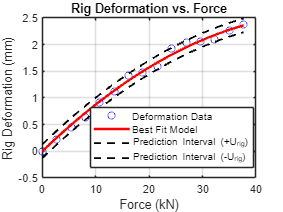

% Code here for figure
% Code for plotting the rig deformation data, best fit model, and prediction interval
figure;
hold on;
grid on;
box on;

% Plot deformation data
scatter(F_rig_N / 1000, D_rig_mm, 'bo', 'DisplayName', 'Deformation Data');  % Force in kN

% Plot the best fit model (assuming quadratic model for this example)
F_fit = linspace(min(F_rig_N), max(F_rig_N), 100);  % Force range for prediction
D_fit = curve24(F_fit);  % Calculate deformation using the quadratic fit
plot(F_fit / 1000, D_fit, 'r-', 'LineWidth', 2, 'DisplayName', 'Best Fit Model');  % Force in kN

% Plot the prediction interval
D_upper = D_fit + U_rig_mm;  % Upper bound of prediction interval
D_lower = D_fit - U_rig_mm;  % Lower bound of prediction interval
plot(F_fit / 1000, D_upper, 'k--', 'LineWidth', 1.5, 'DisplayName', 'Prediction Interval (+U_{rig})');
plot(F_fit / 1000, D_lower, 'k--', 'LineWidth', 1.5, 'DisplayName', 'Prediction Interval (-U_{rig})');

% Labels and title
xlabel('Force (kN)');
ylabel('Rig Deformation (mm)');
title('Rig Deformation vs. Force');
legend('Location', 'best');

hold off;

#### Problem 27

Using the rig displacement model and the dog bone force data, correct the dog bone displacement data by removing the rig deformation. *(Note: There should be a corrected displacement value for each of the corresponding force values from the model.)(Hint: The maximum correction should be between -2.1 and -1.9 mm.)*

% Code here to solve for corrected dog bone displacement
D_corrected_mm = denoised_X_dogbone_mm - curve24(denoised_F_dogbone_N);
maximumCorrection = max(curve24(denoised_F_dogbone_N));

#### Problem 28

Using the corrected data, what is the force, $F_{\textrm{fail}}$, in **Newtons** and displacement, $D_{\textrm{fail}}$, in millimeters of the dog bone at failure? *(Hint: The force should be between 24 and 25 kN and the displacement between 7.0 and 7.4 mm.)*

% Code here to solve for updated dog bone F_fail_displacement
F_fail_N = denoised_F_dogbone_N(end);  % Force at failure
D_fail_mm = D_corrected_mm(end);  % Displacement at failure
% Output the results
fprintf('F_fail = %.4f N, D_fail = %.4f mm\n', F_fail_N + delta_F_N, D_fail_mm + delta_X_mm);  % Output the result

F_fail = 24527.0826 N, D_fail = 7.2613 mm
